# Behavioral analysis of multi-reard experiment on 12/21/2023

## Experiment infomation

Recording data: 12/20/2024

Number of sessions: 4

Reward flavior: pear and banana

%% Experiment info
load('reward_info.mat')
n_session = size(reward_session,1);
reward_summary = cell(n_session,4);
for i = 1:n_session
    for fd = 1:4
        fl = reward_session(i,fd);
        if fl ~= 0
            reward_summary{i,fd} = reward_list{fl};
        end
    end
end
reward_summary

reward_summary = 2×4 cell array
    {'banana'}    {'grape' }    {0×0 double}    {0×0 double}
    {'grape' }    {'banana'}    {0×0 double}    {0×0 double}


## Data structure

cortex: reward and TTL signals

cdp: bat position and acceleration

reward: feeder landing

camera: camera recordings

analysis: directory to save all outputs of analysis

Serial_numbers.txt: serial number of tags

%% Directory
data_dir = pwd;
fprintf('Data directory is %s',pwd)

Data directory is Z:\users\Tatsumi\data\MultiReward\recording\groupC\231221

% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));
% cdp
cdp_dir     =   dir(fullfile(data_dir,'cdp','*cdp*.txt'));
cdp_file    =   fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir  =   dir(fullfile(data_dir,'*Serial_numbers*'));
serial_file =   fullfile(serial_dir.folder,serial_dir.name);
% analysis
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing

### Preprocess raw tag data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_file); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,0,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Extracted data are found in the directory.


Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

% Extract behaviors
beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0() % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

Behavior data are found in the directory.


Behavior data are loaded.


### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

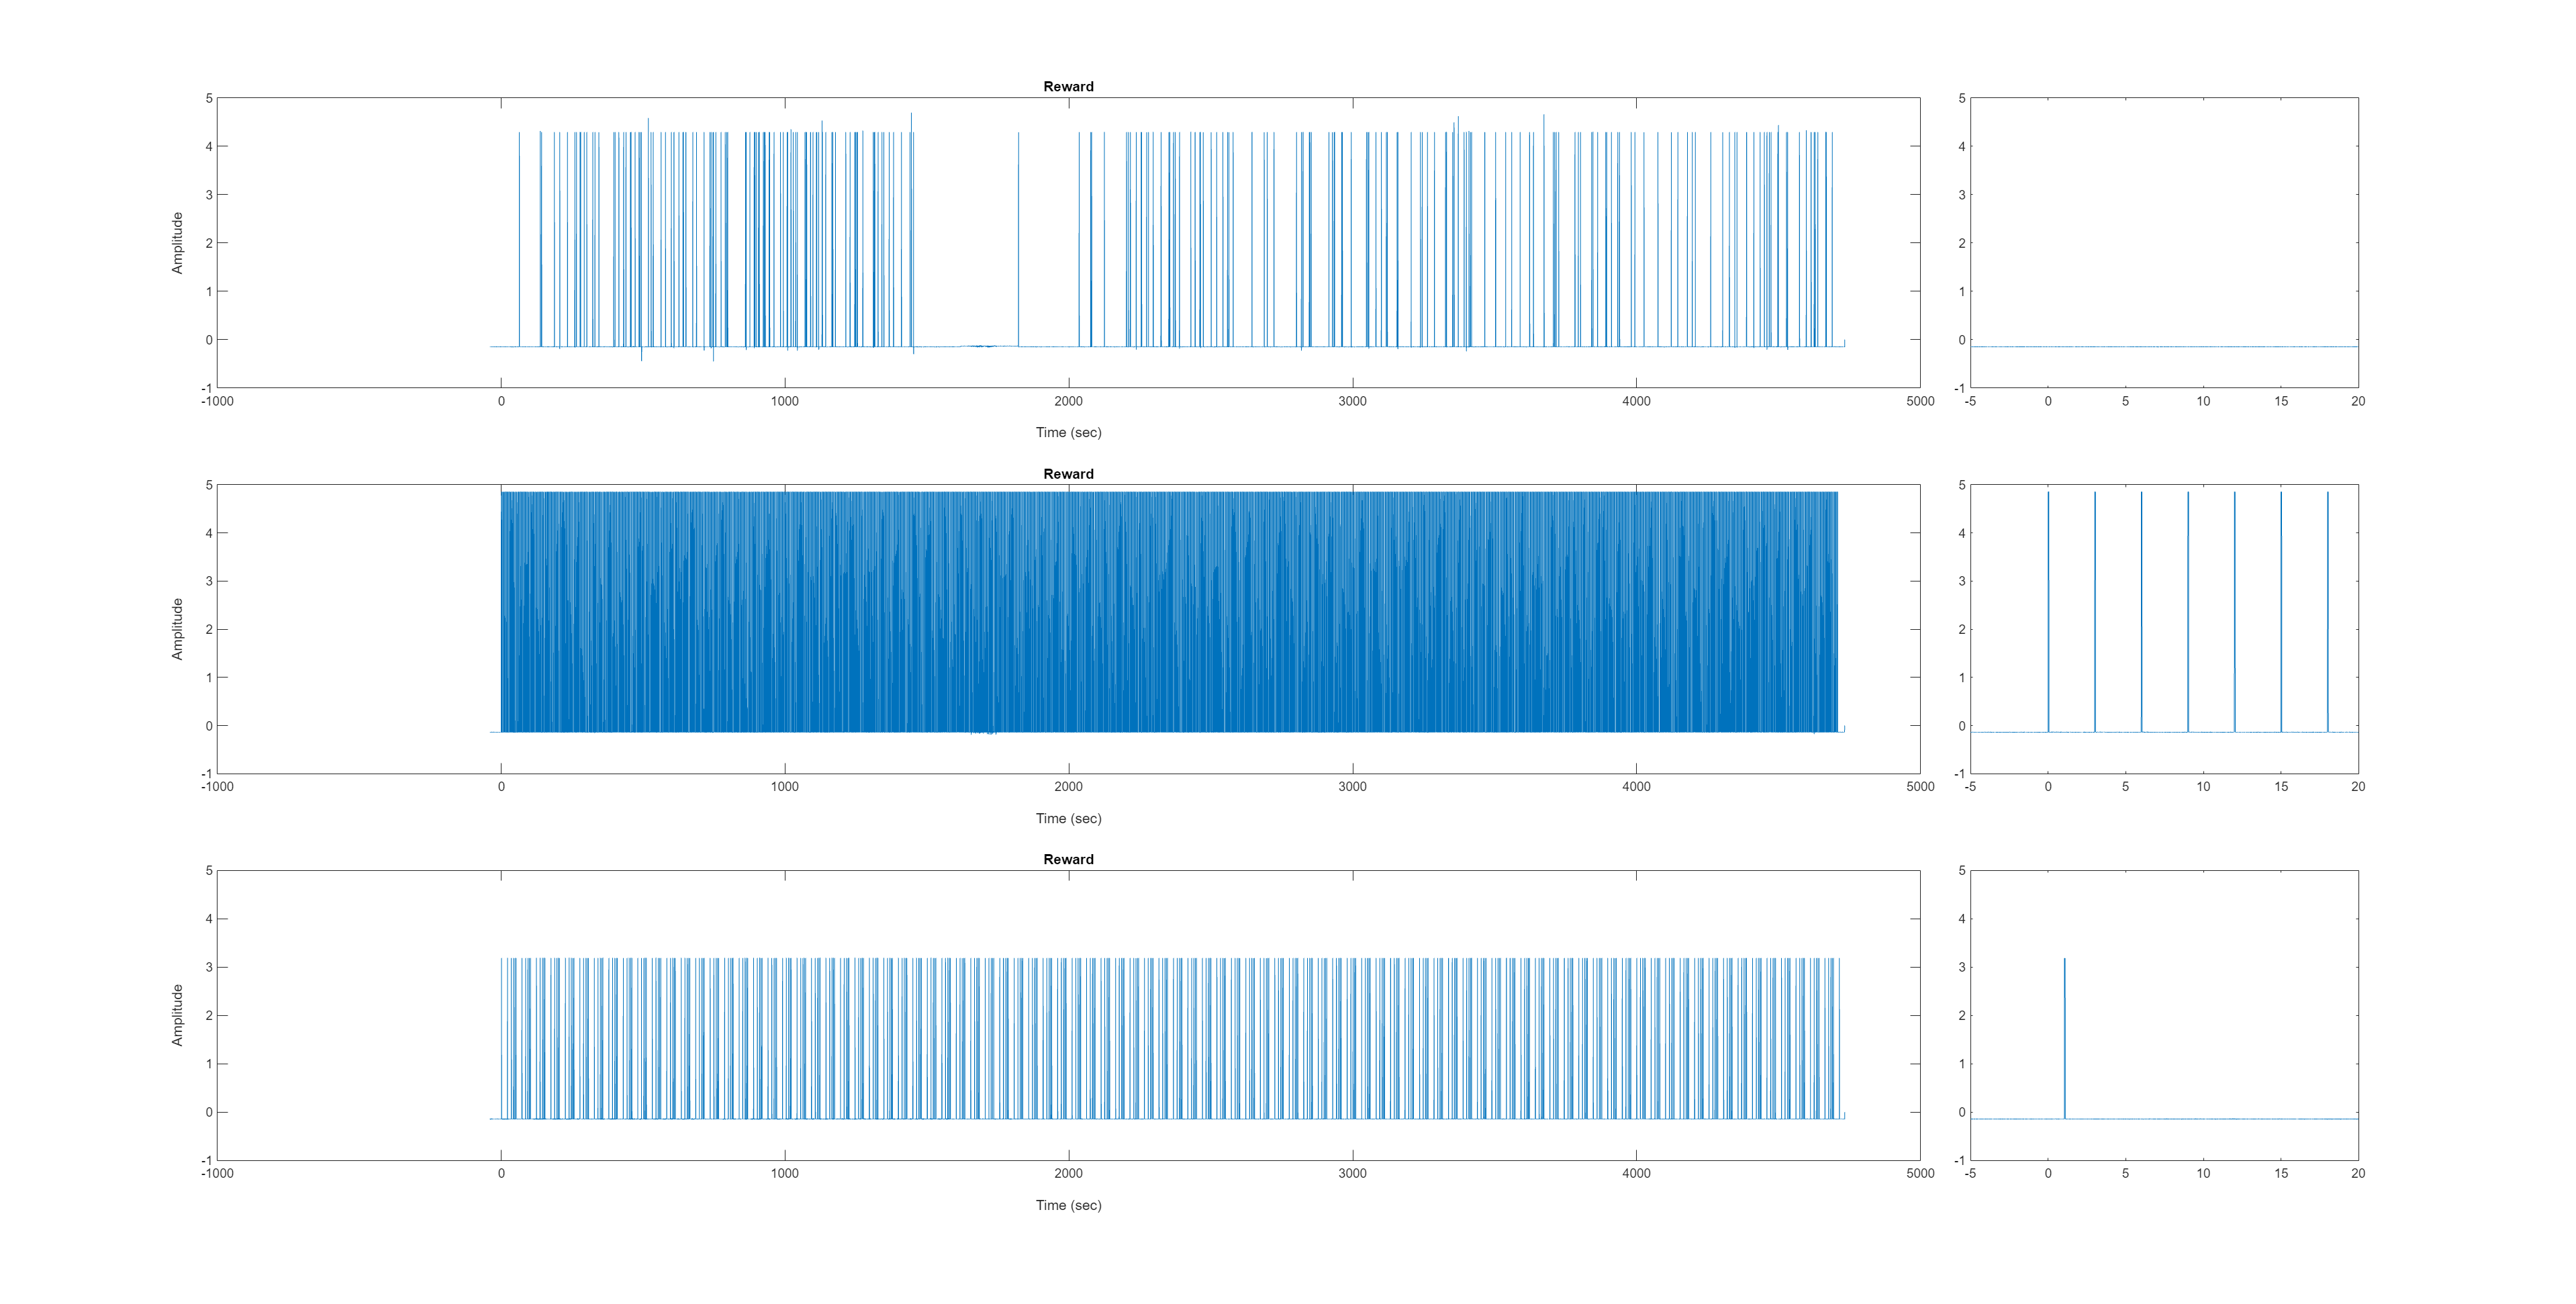

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(res_dir_path,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end
AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);

save(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')

#### Aligning the reward signals to the global time

Reward data for each session have timestamps based on their local time, so they should be concatenated and assigned with the global timestamps. Also, add some columns to the output data.

[reward,reward_field] = concatenate_reward('reward');
% save(fullfile('analysis','extracted_reward.mat'),'reward','reward_field')
[reward,reward_field,t_session] = process_reward_data(reward,reward_field,reward_session,AnalogSignals,rec_date);

Final MinPeakDistance was 0.5 
238 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


save(fullfile('analysis','processed_reward.mat'),'reward','reward_field','reward_list','reward_session')

## Visualization

### Feeder/reward preference

Let's look at the feeder activation timings to see if the bats changed their feeder preference when the smoothie was switched.

First of all, check only one bat.

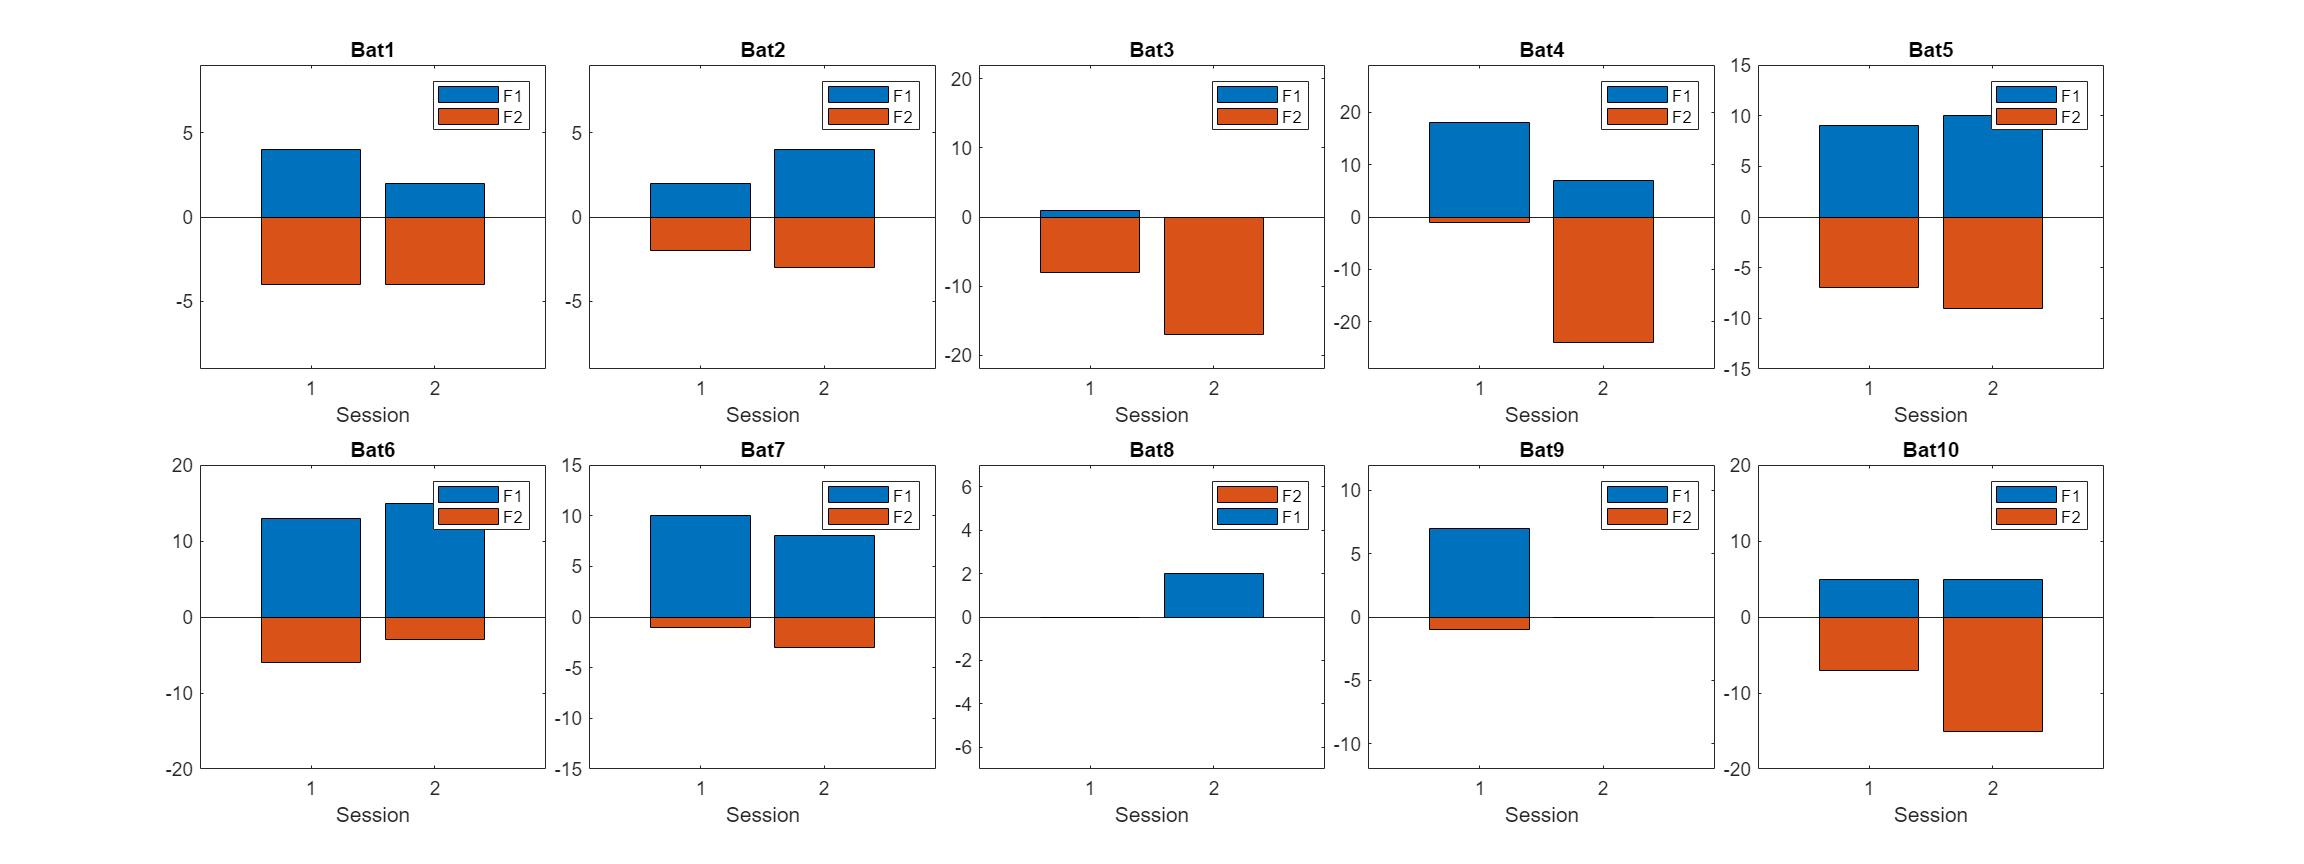

fig = figure;
fontsize(fig, 24, "points")
set(gcf, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
for bb = 1:n_tags
    feeder_pref = zeros(n_session,2);
    for ss = 1:n_session
        for ff = 1:2 % number of active feeder
            feeder_pref(ss,ff) = size(reward(reward(:,ismember(reward_field,{'bat_ID'}))==bb & reward(:,ismember(reward_field,{'session'}))==ss & reward(:,ismember(reward_field,{'activated_feeder'}))==ff,:),1);
        end
    end
    max_cnt = max(max(feeder_pref));
    feeder_pref(:,2) = feeder_pref(:,2)*-1;
    nexttile
    bar(categorical(1:n_session),feeder_pref,'stacked')
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Session')
    ylabel('')
    legend({"F1","F2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end

saveas(gcf,fullfile(fig_dir_path,'Feeder_preference.png'))

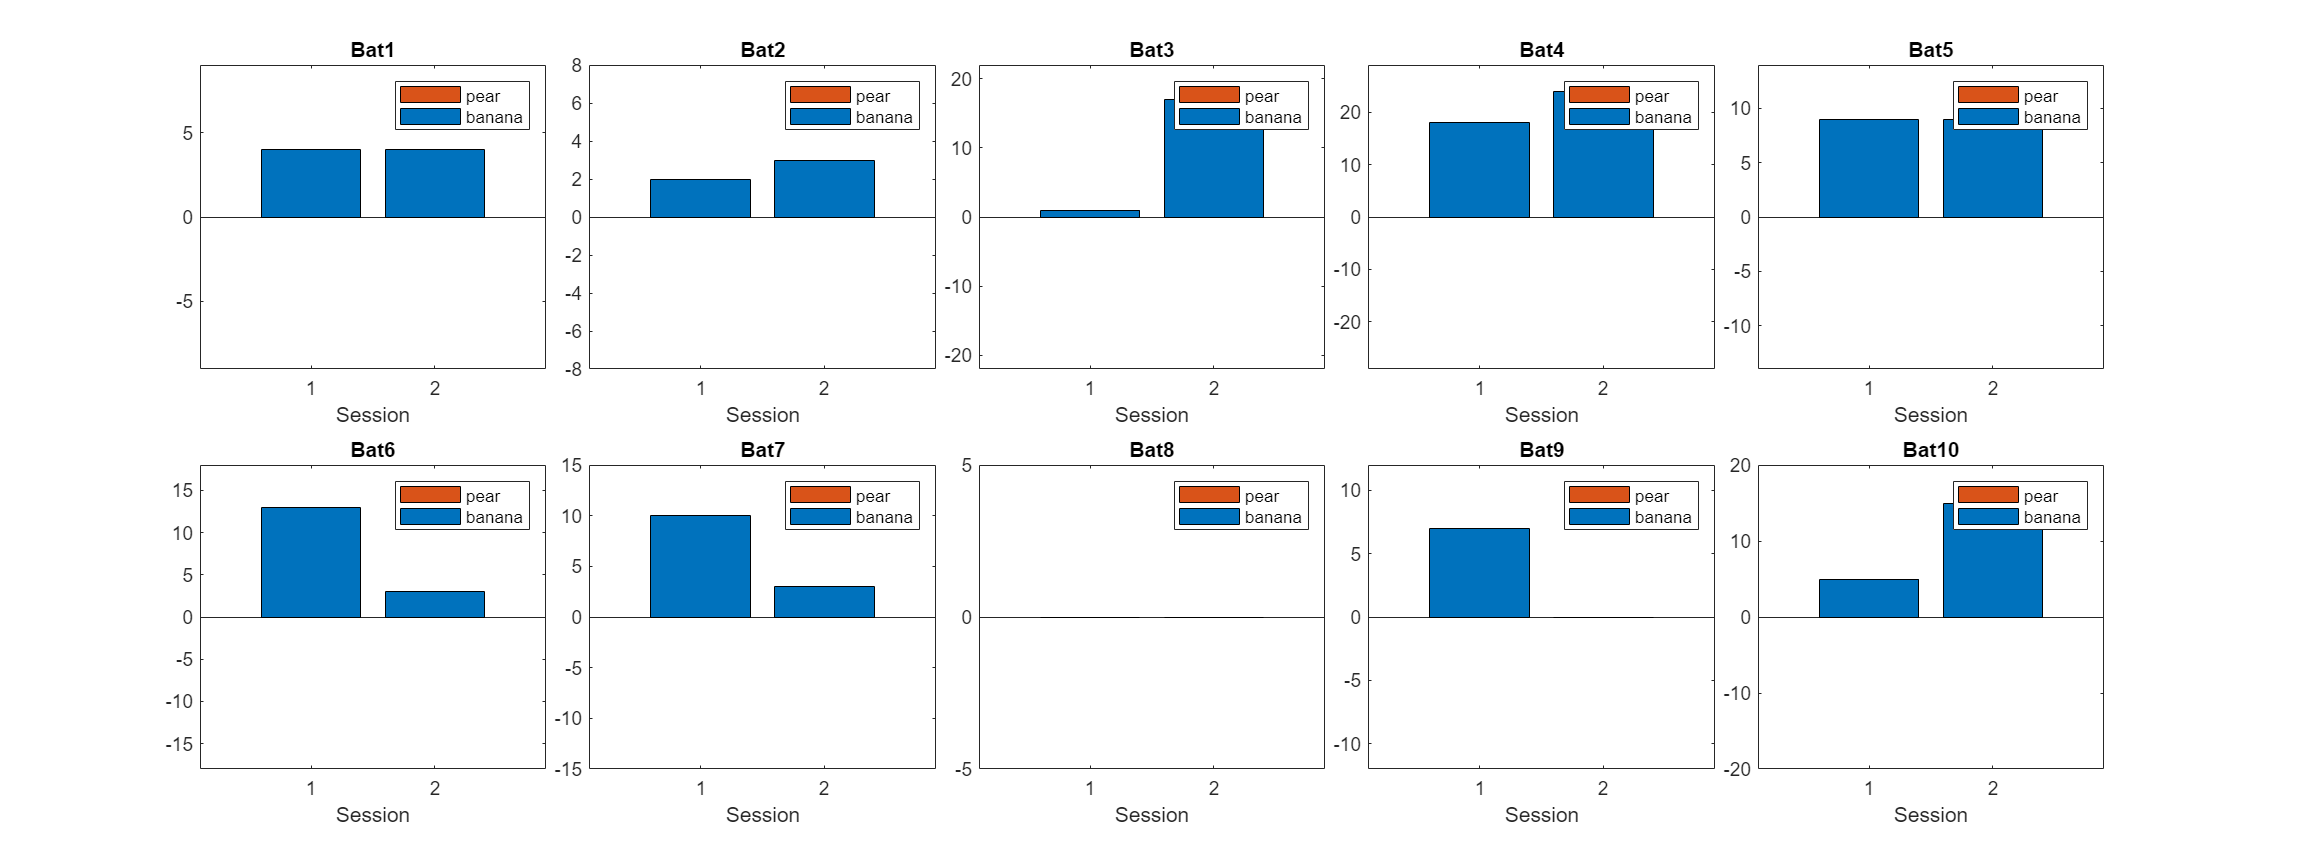

fig = figure;
fontsize(fig, 24, "points")
set(gcf, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
for bb = 1:n_tags
    feeder_pref = zeros(n_session,2);
    for ss = 1:n_session
        for rwd = 1:2 % number of active feeder
            feeder_pref(ss,rwd) = size(reward(reward(:,ismember(reward_field,{'bat_ID'}))==bb & reward(:,ismember(reward_field,{'session'}))==ss & reward(:,ismember(reward_field,{'reward_type'}))==rwd,:),1);
        end
    end
    max_cnt = max(max(feeder_pref));
    feeder_pref(:,2) = feeder_pref(:,2)*-1;
    nexttile
    bar(categorical(1:n_session),feeder_pref,'stacked')
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Session')
    ylabel('')
    legend({reward_list{1},reward_list{2}})
    ylim([-1*(max_cnt+5),max_cnt+5])
end

saveas(gcf,fullfile(fig_dir_path,'reward_preference.png'))

Also, the cumulative frequency of landings to each feeder is shown here:

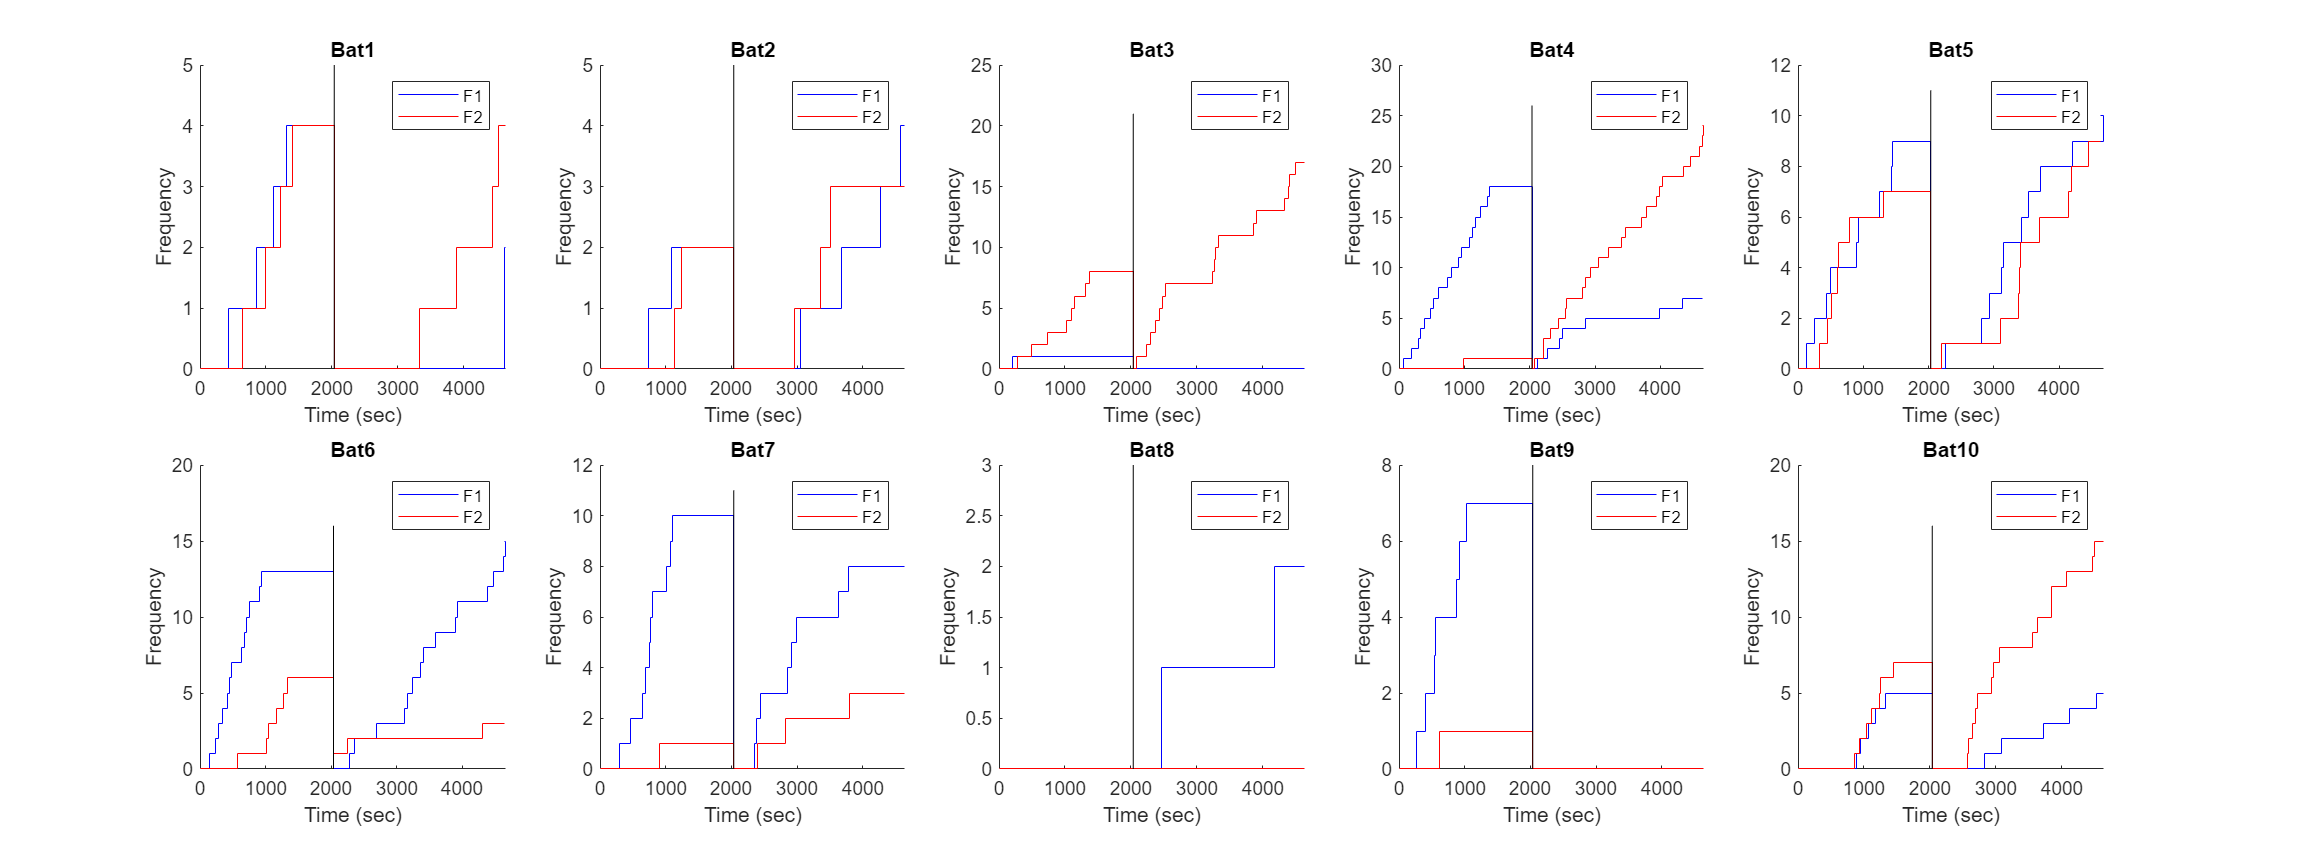

t_session = zeros(n_session,1);
for i=2:n_session
    t_session(i) = reward(find(reward(:,ismember(reward_field,'session'))==i,1,'first'),ismember(reward_field,'global_time'));
end

fig = figure;
fontsize(fig, 24, "points")
set(gcf, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
fig_clr = {'b','r'};
for bb = 1:n_tags
    nexttile
    hold on
    for ff = 1:2 % number of active feeder
        
        t_rw_cum = [];
        rw_cum = [];
        
        for ss = 1:n_session
            t_rw_cum = [t_rw_cum; t_session(ss)];
            rw_cum = [rw_cum; 0];
    
            t_rw_cum = [t_rw_cum; reward(reward(:,ismember(reward_field,'bat_ID'))==bb & ...
                reward(:,ismember(reward_field,'activated_feeder'))==ff & ...
                reward(:,ismember(reward_field,'session'))==ss,...
                ismember(reward_field,'global_time'))];
            rw_cum = [rw_cum;cumsum(ones(size(reward( ...
                reward(:,ismember(reward_field,'bat_ID'))==bb & ...
                reward(:,ismember(reward_field,'activated_feeder'))==ff & ...
                reward(:,ismember(reward_field,'session'))==ss,:),1),1))];
        end
        t_rw_cum = [t_rw_cum; t(end)];
        rw_cum = [rw_cum; rw_cum(end)];
    
        stairs(t_rw_cum,rw_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (sec)')
    ylabel('Frequency')
    
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss),t_session(ss)],[y_lim(1),y_lim(2)+1],'k')
    end
    hold off

    f=get(gca,'Children');
    legend([f(length(f)),f(length(f)-1)],'F1','F2')
end

saveas(gcf,fullfile(fig_dir_path,'Cumulative_feeder_preference.png'))

### Detect landings based on the cdp data

#### Load data

load the extracted reward and behavior data.

load(fullfile(res_dir_path,'processed_reward.mat')) % reward
beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
load(fullfile(beh_dir.folder,beh_dir.name)) % behavior

#### Detect all landings on the feeders and non-feeder places

Extract the start/end timings and the position of all the landings. The extracted information is saved into `Landings`.

Landings   =   cell(n_tags,12); % Save the extracted behavior at the feeders
Landings_fields = cell(1,12); % field name of f

blanding = 1 - bflying; % Timing of landings

% Feeder coordinates
% r_fd = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % Feeder position
[r_fd,~] = r_feeder_calibrate('Y:\users\Tatsumi\Data\Flight_room_test\240120_feeder_calibration');

% Summarize the information for all the landings
for bb = 1:n_tags

    landing_start    =   find(diff([blanding(1,bb);blanding(:,bb)])==1); % The index of the variable t for the start of landings
    landing_end      =   find(diff([blanding(:,bb);blanding(end,bb)])==-1); % The index of the variable t for the end of landings

    % Omit the initial/last landing in some cases:
    if blanding(1,bb)~=1 % if the bat was flying when the recording started
        if blanding(end,bb)~=1 % if the bat was flying when the recording finished
        else % if the bat was landing when the recording finished
            landing_start(end) = [];
        end
    elseif blanding(1,bb)==1 % if the bat was landing when the recording started
        if blanding(end,bb)~=1 % if the bat was flying when the recording finished
            landing_end(1) = []; 
        else % if the bat was landing when the recording finished
            landing_start(end) = [];
            landing_end(1) = [];
        end
    end
    if length(landing_start) ~= length(landing_end)
        error('# of takeoff and landing mismatch. Check the detection.')
    else
        fprintf('%dth bat: %d landing was detected from the cdp data. \n',bb, length(landing_start))
    end

    n_land = length(landing_start); % Number of landings
    r_land = cell(n_land,1); % Position of all bats when a bat is landing
    r_land_median = zeros(n_land,3); % Median position of landings
    feeder_distance = zeros(n_land,4); % Distance to each feeder from landing spots
    closest_feeder = zeros(n_land,2); % Distance and identity evaluation of closest feeder at landing
    is_fd_land = false(n_land,1); % true if a landing on the feeders
    for ll = 1:n_land
        r_land{ll}   =   r(landing_start(ll):landing_end(ll),:,:);
        r_land_median(ll,:)   =   median(r_land{ll}(:,:,bb));
        for fd = 1:4
            feeder_distance(ll,fd) = vecnorm(r_fd(fd,:)-r_land_median(ll,:)); % Distance to each feeder
        end
        [min_dist, feeder_id] = min(feeder_distance(ll,:));
        closest_feeder(ll,1) = min_dist; % Distance to the closest feeder
        closest_feeder(ll,2) = feeder_id; % Identity of the closest feeder
        if min_dist < 0.2
            is_fd_land(ll) = true;
        end
    end

    % Time fraction of being close to the conspecifics
    th_with_oth = 0.2; % threshold distance to evalute if the target bat was with his conspecifcs
    len_land = t(landing_end) - t(landing_start);
    d_oth = cell(n_land,1); % distance to conspecifics
    len_with_oth = zeros(n_land,n_tags); % length of landing with conspecifics in sec
    % is_not_self = false(1,n_tags); is_not_self(bb) = true; % to exclude the target bat itself
    for ll = 1:n_land
        for bbb = 1:n_tags
            d_oth{ll}(:,bbb) = vecnorm(r_land{ll}(:,:,bbb)-r_land{ll}(:,:,bb),2,2);
        end
        len_with_oth(ll,:) = sum(d_oth{ll} < 0.2,1) / 100;
        len_with_oth(ll,bb) = 0; % exclude the target bat itself
    end
    prob_with_oth = len_with_oth ./ len_land;

    % assign session
    session_land = zeros(n_land,1);
    for ll = 1:n_land
        session_land(ll) = find(t(landing_start(ll))>t_session,1,'last');
    end

    % Save information into a variable
    Landings{bb,1} = t(landing_start);
    Landings{bb,2} = t(landing_end);
    Landings_fields{1} = 'land_start_t';
    Landings_fields{2} = 'land_end_t';    
    Landings{bb,3} = n_land;
    Landings_fields{3} = 'n_land';
    Landings{bb,4} = r_land;
    Landings{bb,5} = r_land_median;
    Landings_fields{4} = 'r_land';
    Landings_fields{5} = 'r_land_med';
    Landings{bb,6} = d_oth;
    Landings{bb,7} = len_with_oth;
    Landings{bb,8} = prob_with_oth;
    Landings_fields{6} = 'd_oth';
    Landings_fields{7} = 'len_with_oth';
    Landings_fields{8} = 'prob_with_oth';
    Landings{bb,9} = feeder_distance;
    Landings{bb,10} = closest_feeder;
    Landings{bb,11} = is_fd_land;
    Landings_fields{9} = 'fd_dist';
    Landings_fields{10} = 'fd_closest';
    Landings_fields{11} = 'is_fd_land';
    Landings{bb,12} = session_land;
    Landings_fields{12} = 'session';
end

1th bat: 79 landing was detected from the cdp data. 
2th bat: 58 landing was detected from the cdp data. 
3th bat: 85 landing was detected from the cdp data. 
4th bat: 99 landing was detected from the cdp data. 
5th bat: 106 landing was detected from the cdp data. 
6th bat: 124 landing was detected from the cdp data. 
7th bat: 51 landing was detected from the cdp data. 
8th bat: 3 landing was detected from the cdp data. 
9th bat: 48 landing was detected from the cdp data. 
10th bat: 68 landing was detected from the cdp data. 


The detected landings are validated visually by checking the bat's positions around the landing starts.

%% Visualize all landing
for bb = 1:n_tags

    t_land = Landings{bb,1};
    n_land = Landings{bb,3};
    is_fd_land = Landings{bb,11};

    range_draw = 20; % range to visualize around the feeder activation timing
    pre_t = 5; % time to draw before landing starts
    
    figure('Units','normalized','Position',[0.15,0.05,0.7,0.9],'Visible','off')
    tl = tiledlayout(5,5,"TileSpacing",'loose');
    title(tl,sprintf('Bat%d: %d sec after landings',bb,range_draw))
    fig_cnt = 1;
    save_cnt = 1;
    for ll = 1:n_land
        idx_t = find(ismember(round(t,2),round(t_land(ll),2)));
            if idx_t > 100*pre_t && idx_t < T - 100*range_draw
                r_plot = r(idx_t-100*pre_t:idx_t+100*range_draw,:,bb);
                t_plot = (-1*pre_t:0.01:range_draw)' + t(idx_t);
                l_plot = blanding(idx_t-100*pre_t:idx_t+100*range_draw,bb);
            elseif idx_t <= 100*pre_t
                r_plot = r(1:idx_t+100*range_draw,:,bb);
                t_plot = (-1*(idx_t-1)/100:0.01:range_draw)' + t(idx_t);
                l_plot = blanding(1:idx_t+100*range_draw,bb);
            else
                r_plot = r(idx_t-100*pre_t:end,:,bb);
                t_plot = (-1*pre_t:0.01:(T-idx_t)/100)' + t(idx_t);
                l_plot = blanding(idx_t-100*pre_t:end,bb);
            end
        n = length(t_plot);
        CD = [uint8(jet(n)*255) uint8(ones(n,1))].';
    
        % t_plot = t(idx_feeder-100*60:idx_feeder+100*30);
    
        nexttile([1,4])
        hold on
        plot(t_plot,r_plot,'LineWidth',1);
        plot([t(idx_t),t(idx_t)],[-3,3],'k')
        area(t_plot,l_plot,'FaceAlpha',0.2,'LineStyle','none','FaceColor',[0.3010 0.7450 0.9330])
        hold off
        xlim([t(idx_t)-pre_t,t(idx_t)+range_draw])
        ylim([-3,3])
        if is_fd_land(ll)
            title(sprintf('%dth landing: feeder',ll))
        else
            title(sprintf('%dth landing: non-feeder',ll))
        end
        xlabel('Time (sec)')
        ylabel('Position (m)')
        legend({'x','y','z','Beam blocked'})
    
        nexttile([1,1])
        hold on
        p = plot(r_plot(:,1),r_plot(:,2));
        drawnow
        set(p.Edge, 'ColorBinding','interpolated', 'ColorData',CD)
        scatter(r(idx_t,1,bb),r(idx_t,2,bb),20,'k','filled')

        rectangle('Position',[r_fd(1,1)-0.1,r_fd(1,2)-0.1,0.2,0.2],'EdgeColor','k')
        rectangle('Position',[r_fd(2,1)-0.1,r_fd(2,2)-0.1,0.2,0.2],'EdgeColor','k')
        rectangle('Position',[r_fd(3,1)-0.1,r_fd(3,2)-0.1,0.2,0.2],'EdgeColor','c')
        rectangle('Position',[r_fd(4,1)-0.1,r_fd(4,2)-0.1,0.2,0.2],'EdgeColor','c')
        hold off
        title('Top view')
        xlabel('x (m)')
        ylabel('y (m)')
        xlim([r_lim(1,1),r_lim(1,2)])
        ylim([r_lim(2,1),r_lim(2,2)])
    
        % nexttile([1,1])
        % hold on
        % p = plot(r_plot(:,2),r_plot(:,3));
        % drawnow
        % set(p.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
        % scatter(r(idx_feeder,2,bb),r(idx_feeder,3,bb),20,'k','filled')
        % hold off
        % xlabel('y')
        % ylabel('z')
        % xlim([r_lim(2,1),r_lim(2,2)])
        % ylim([r_lim(3,1),r_lim(3,2)])
    
        if fig_cnt < 5
            fig_cnt = fig_cnt + 1;
        else
            if ll ~= n_land
                saveas(gcf,fullfile(res_dir_path,'figure',['AllLandings_bat' num2str(bb) '_' num2str(save_cnt) '.png']));
                save_cnt = save_cnt + 1;
                close all

                figure('Units','normalized','Position',[0.15,0.05,0.7,0.9],'Visible','off')
                tl = tiledlayout(5,5,"TileSpacing",'loose');
                title(tl,sprintf('Bat%s',num2str(bb)))
                fig_cnt = 1;
            end
        end
    end

    saveas(gcf,fullfile(res_dir_path,'figure',['AllLandings_bat' num2str(bb) '_' num2str(save_cnt) '.png']));
    close all
end

#### Landings on only the feeders

Landings_fd   =   cell(n_tags,11); % Save the extracted behavior at the feeders
Landings_fd_fields = Landings_fields; % field name of Landings_fd

for bb = 1:n_tags
    is_fd_land = Landings{bb,11};
    n_fd_land = sum(is_fd_land); % number of landings on feeders
    for idx = 1:size(Landings,2)
        if idx == 3
           Landings_fd{bb,idx} = n_fd_land;
        else
            Landings_fd{bb,idx} = Landings{bb,idx}(is_fd_land,:);
        end
    end
end

%% Visualize all landing
for bb = 1:n_tags

    t_land = Landings_fd{bb,1};
    n_land = Landings_fd{bb,3};

    range_draw = 20; % range to visualize around the feeder activation timing
    pre_t = 5; % time to draw before landing starts
    
    figure('Units','normalized','Position',[0.15,0.05,0.7,0.9],'Visible','off')
    tl = tiledlayout(5,5,"TileSpacing",'loose');
    title(tl,sprintf('Bat%d: %d sec after landings',bb,range_draw))
    fig_cnt = 1;
    save_cnt = 1;
    for ll = 1:n_land
        idx_t = find(ismember(round(t,2),round(t_land(ll),2)));
            if idx_t > 100*pre_t && idx_t < T - 100*range_draw
                r_plot = r(idx_t-100*pre_t:idx_t+100*range_draw,:,bb);
                t_plot = (-1*pre_t:0.01:range_draw)' + t(idx_t);
                l_plot = blanding(idx_t-100*pre_t:idx_t+100*range_draw,bb);
            elseif idx_t <= 100*pre_t
                r_plot = r(1:idx_t+100*range_draw,:,bb);
                t_plot = ((idx_t-1)/100:0.01:range_draw)' + t(idx_t);
                l_plot = blanding(1:idx_t+100*range_draw,bb);
            else
                r_plot = r(idx_t-100*pre_t:end,:,bb);
                t_plot = (-1*pre_t:0.01:(T-idx_t)/100)' + t(idx_t);
                l_plot = blanding(idx_t-100*pre_t:end,bb);
            end
        n = length(t_plot);
        CD = [uint8(jet(n)*255) uint8(ones(n,1))].';
    
        % t_plot = t(idx_feeder-100*60:idx_feeder+100*30);
    
        nexttile([1,4])
        hold on
        plot(t_plot,r_plot,'LineWidth',1);
        plot([t(idx_t),t(idx_t)],[-3,3],'k')
        area(t_plot,l_plot,'FaceAlpha',0.2,'LineStyle','none','FaceColor',[0.3010 0.7450 0.9330])
        hold off
        xlim([t(idx_t)-pre_t,t(idx_t)+range_draw])
        ylim([-3,3])
        title(sprintf('%dth landing: feeder',ll))
        xlabel('Time (sec)')
        ylabel('Position (m)')
        legend({'x','y','z','Beam blocked'})
    
        nexttile([1,1])
        hold on
        p = plot(r_plot(:,1),r_plot(:,2));
        drawnow
        set(p.Edge, 'ColorBinding','interpolated', 'ColorData',CD)
        scatter(r(idx_t,1,bb),r(idx_t,2,bb),20,'k','filled')

        rectangle('Position',[r_fd(1,1)-0.1,r_fd(1,2)-0.1,0.2,0.2],'EdgeColor','k')
        rectangle('Position',[r_fd(2,1)-0.1,r_fd(2,2)-0.1,0.2,0.2],'EdgeColor','k')
        rectangle('Position',[r_fd(3,1)-0.1,r_fd(3,2)-0.1,0.2,0.2],'EdgeColor','c')
        rectangle('Position',[r_fd(4,1)-0.1,r_fd(4,2)-0.1,0.2,0.2],'EdgeColor','c')
        hold off
        title('Top view')
        xlabel('x (m)')
        ylabel('y (m)')
        xlim([r_lim(1,1),r_lim(1,2)])
        ylim([r_lim(2,1),r_lim(2,2)])
    
        % nexttile([1,1])
        % hold on
        % p = plot(r_plot(:,2),r_plot(:,3));
        % drawnow
        % set(p.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
        % scatter(r(idx_feeder,2,bb),r(idx_feeder,3,bb),20,'k','filled')
        % hold off
        % xlabel('y')
        % ylabel('z')
        % xlim([r_lim(2,1),r_lim(2,2)])
        % ylim([r_lim(3,1),r_lim(3,2)])
    
        if fig_cnt < 5
            fig_cnt = fig_cnt + 1;
        else
            if ll ~= n_land
                saveas(gcf,fullfile(res_dir_path,'figure',['FeederLandings_bat' num2str(bb) '_' num2str(save_cnt) '.png']));
                save_cnt = save_cnt + 1;
                close all

                figure('Units','normalized','Position',[0.15,0.05,0.7,0.9],'Visible','off')
                tl = tiledlayout(5,5,"TileSpacing",'loose');
                title(tl,sprintf('Bat%d: %d sec after landings',bb,range_draw))
                fig_cnt = 1;
            end
        end
    end

    saveas(gcf,fullfile(res_dir_path,'figure',['FeederLandings_bat' num2str(bb) '_' num2str(save_cnt) '.png']));
    close all
end

Compare the number of detected landings between the cdp and the reward delivery data.

th_d_fd = 0.2; % threshold of the distance from feeders
for bb = 1:n_tags
    r_land_med = Landings_fd{bb,5};
    n_land = Landings_fd{bb,3};
    
    is_land_f1 = Landings_fd{bb,10}(:,2)==1;
    is_land_f2 = Landings_fd{bb,10}(:,2)==2;
    d_land_f1 = Landings_fd{bb,10}(is_land_f1,1);
    d_land_f2 = Landings_fd{bb,10}(is_land_f2,1);
    is_land_anyf = any([is_land_f1,is_land_f2],2);
    fprintf('Bat%d landings on feeder: cdp %d, analog %d\n',bb,sum(is_land_anyf),sum(reward(:,9)==bb))
end

Bat1 landings on feeder: cdp 14, analog 14
Bat2 landings on feeder: cdp 9, analog 11
Bat3 landings on feeder: cdp 28, analog 26
Bat4 landings on feeder: cdp 52, analog 50
Bat5 landings on feeder: cdp 38, analog 35
Bat6 landings on feeder: cdp 40, analog 37
Bat7 landings on feeder: cdp 25, analog 22
Bat8 landings on feeder: cdp 0, analog 2
Bat9 landings on feeder: cdp 8, analog 8
Bat10 landings on feeder: cdp 29, analog 32


### Feeder/reward preference based on the cdp data

Let's look at the feeder activation timings to see if the bats changed their feeder preference when the smoothie was switched.

First of all, check only one bat.

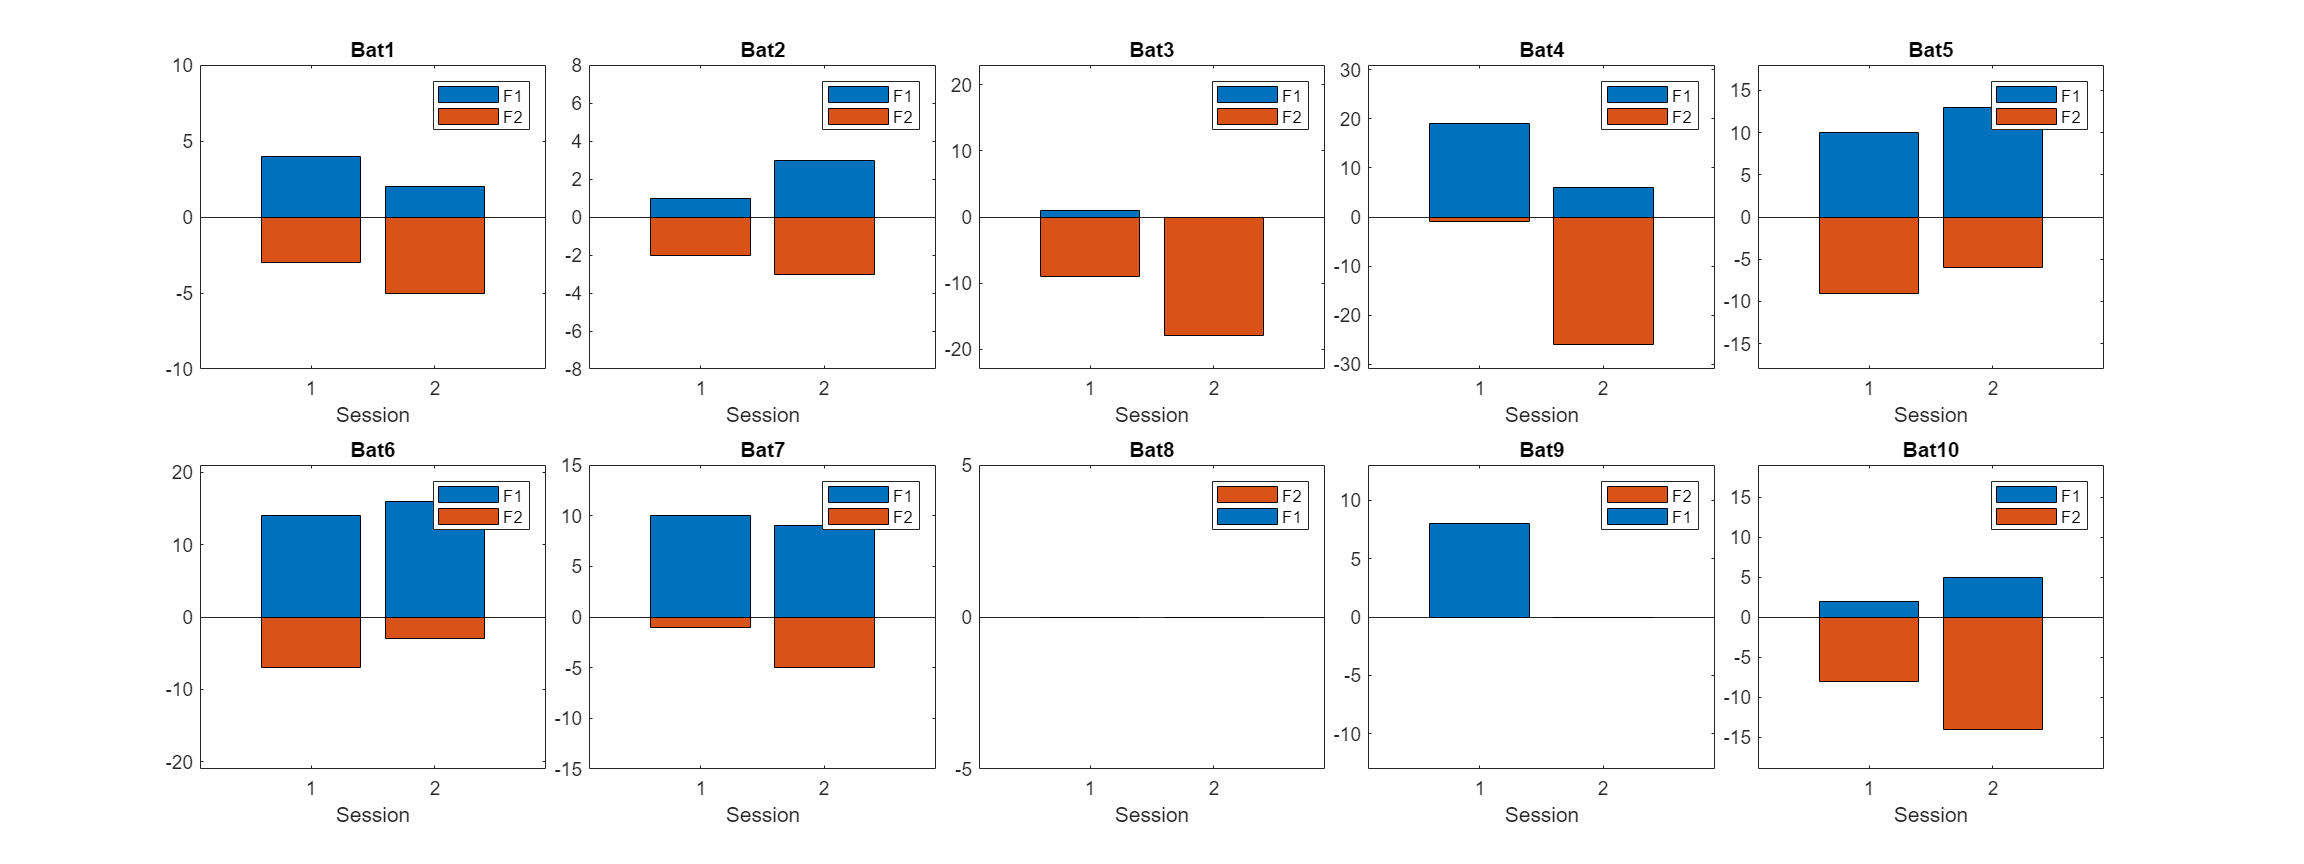

fig = figure;
fontsize(fig, 24, "points")
set(gcf, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
for bb = 1:n_tags
    feeder_pref = zeros(n_session,2);
    for ss = 1:n_session
        for ff = 1:2 % number of active feeder
            feeder_pref(ss,ff) = sum(Landings_fd{bb,ismember(Landings_fd_fields,'session')}==ss & Landings_fd{bb,ismember(Landings_fd_fields,'fd_closest')}(:,2)==ff);
        end
    end
    max_cnt = max(max(feeder_pref));
    feeder_pref(:,2) = feeder_pref(:,2)*-1;
    nexttile
    bar(categorical(1:n_session),feeder_pref,'stacked')
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Session')
    ylabel('')
    legend({"F1","F2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end

saveas(gcf,fullfile(fig_dir_path,'Feeder_preference_cdp.png'))

Also, the cumulative frequency of landings to each feeder is shown here:

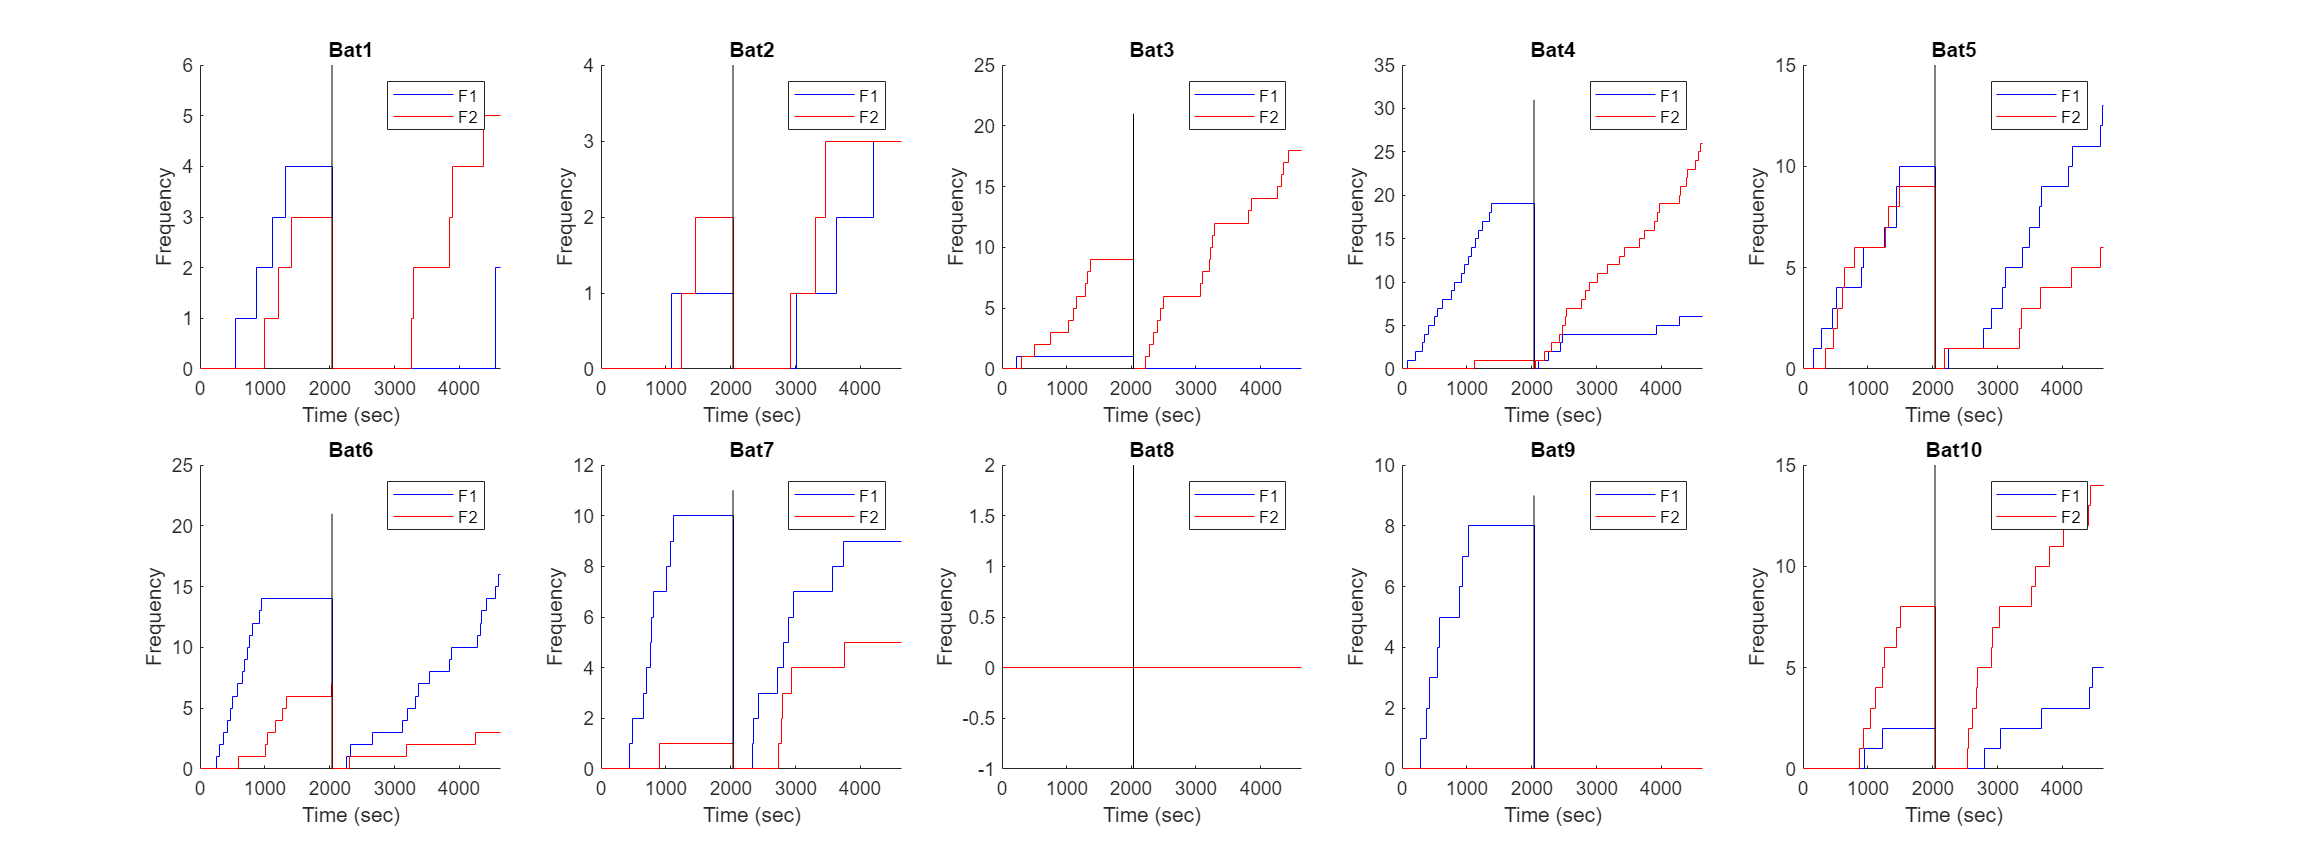

% t_session = zeros(n_session,1);
% for i=2:n_session
%     t_session(i) = reward(find(reward(:,ismember(reward_field,'session'))==i,1,'first'),ismember(reward_field,'global_time'));
% end

fig = figure;
fontsize(fig, 24, "points")
set(gcf, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
fig_clr = {'b','r'};
for bb = 1:n_tags
    nexttile
    hold on
    for ff = 1:2 % number of active feeder
        
        t_rw_cum = [];
        rw_cum = [];
        
        for ss = 1:n_session
            t_rw_cum = [t_rw_cum; t_session(ss)];
            rw_cum = [rw_cum; 0];
            
            t_rw_cum = [t_rw_cum; Landings_fd{bb,1}(Landings_fd{bb,10}(:,2)==ff & Landings_fd{bb,12}==ss)];
            rw_cum = [rw_cum;cumsum(ones(sum(Landings_fd{bb,10}(:,2)==ff & Landings_fd{bb,12}==ss),1))];
        end
        t_rw_cum = [t_rw_cum; t(end)];
        rw_cum = [rw_cum; rw_cum(end)];
    
        stairs(t_rw_cum,rw_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (sec)')
    ylabel('Frequency')
    
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss),t_session(ss)],[y_lim(1),y_lim(2)+1],'k')
    end
    hold off

    f=get(gca,'Children');
    legend([f(length(f)),f(length(f)-1)],'F1','F2')
end

saveas(gcf,fullfile(fig_dir_path,'Cumulative_feeder_preference_cdp.png'))